syms x1 x2

f = @(x1, x2) (x1.^2 + x2.^2 - 1).^2 + (x2.^2 -1).^2

f = function_handle with value:
    @(x1,x2)(x1.^2+x2.^2-1).^2+(x2.^2-1).^2



xx1 = -1.5:0.05:1.5; xx2 = -1.5:0.05:1.5;
[X1, X2] = meshgrid(xx1, xx2);
Z = f(X1, X2);
h1 = figure(1)

h1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [1 1 1]
    Position: [467 311 560 420]
       Units: 'pixels'

  Show all properties


contour(X1, X2, Z, -5:0.2:20);
xlabel('$x_1$', 'interpreter', 'latex');
ylabel('$x_2$', 'Interpreter', 'latex');
hold on
%===================================================
x0 = [1; 1];
g = subs(gradient(f(x1, x2), [x1; x2]), [x1; x2], x0)

$$g = \left(\begin{array}{c} 4\\ 4 \end{array}\right)$$

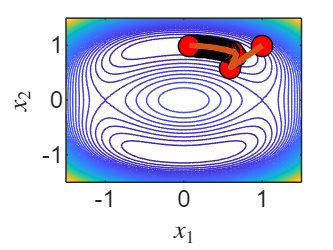

alpha = 0.1; N = 500;
i = 1; x = zeros(2,N); x(:, 1) = x0;
while (norm(g) > 1e-5) & (i < N)
    i = i+1;
    x(:,i) = x(:,i-1) - alpha * g;
    g = subs(gradient(f(x1, x2), [x1; x2]), [x1; x2], x(:,i));
end

scatter(x(1,:), x(2,:), 50, 'r', 'filled', 'MarkerEdgeColor','k')
plot(x(1,:), x(2,:), LineWidth=2)
hold off

%===================================================
x(:,end)

ans =     0.0705
    0.9988


%print(h1,'-depsc','E:\OneDrive\Public\workKMUTT\INC Selection Optimization\Lecture2022\figures\ic2_2025q1.eps');
%!epstopdf "E:\OneDrive\Public\workKMUTT\INC Selection Optimization\Lecture2022\figures\ic2_2025q1.eps"
